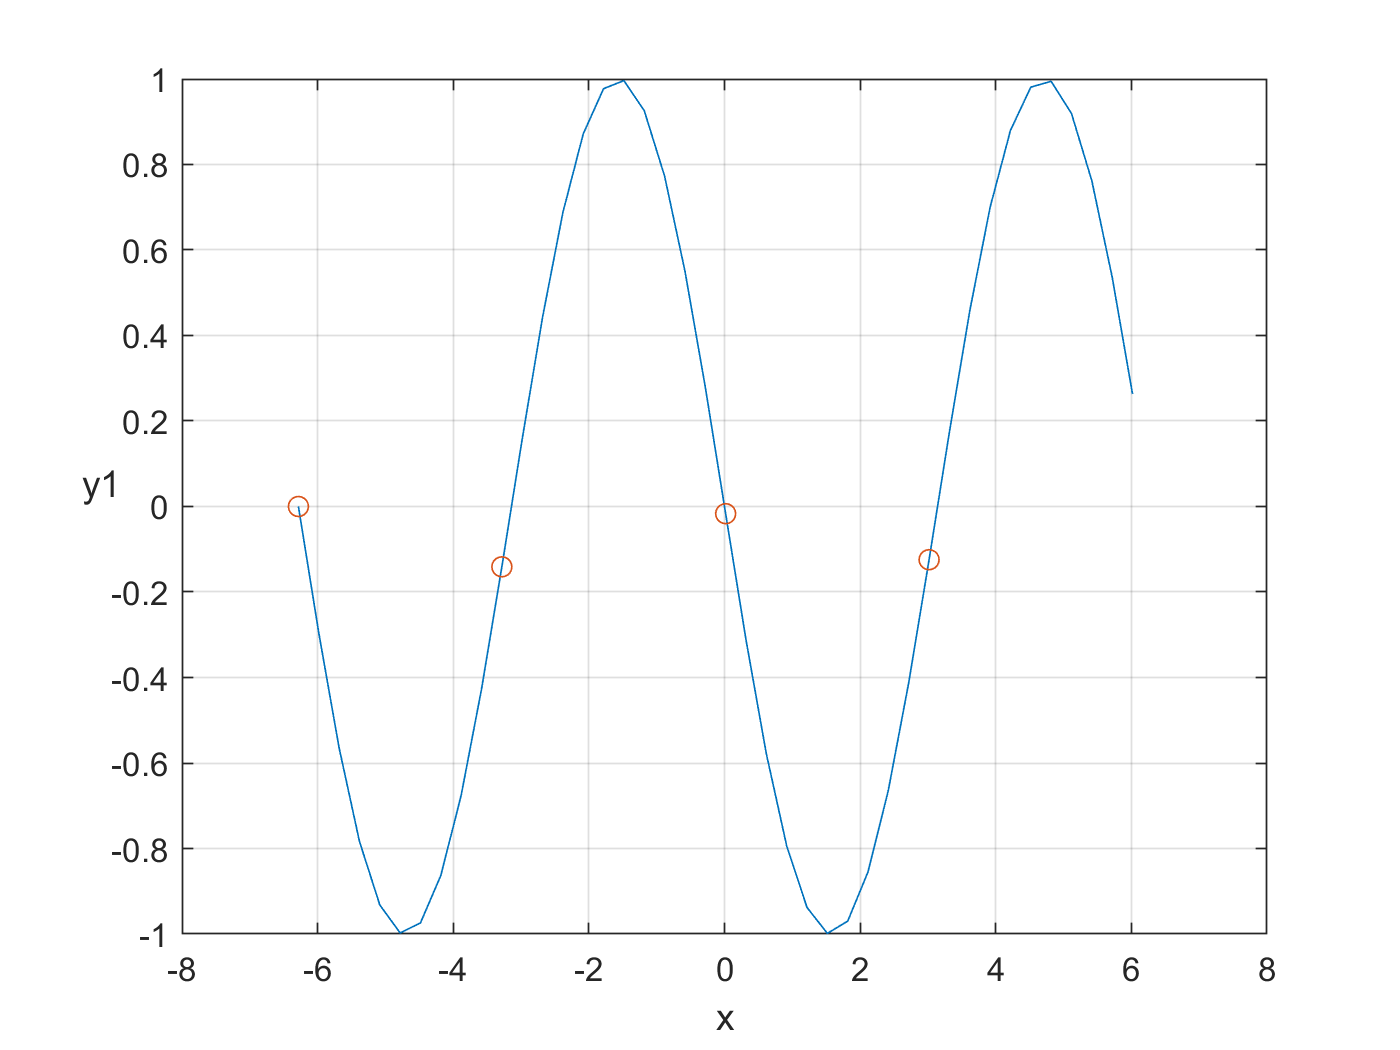

%%Question 1
syms x %create symbolic variable
f = cos(x);
y1 = diff(f);%first derivative
y2 = diff(y1);%second derivative
x = -2*pi:0.3:2*pi;
y1 = -sin(x);
y2 = -cos(x);
figure(1);
plot(x, y1);xlabel('x');ylabel('y1','Rotation',0); %plot out first derivative
grid on; hold on;% from figure1, we can know the stationary points are at 
offset = find(abs(y1) < 0.15);
scatter(x(offset),y1(offset));

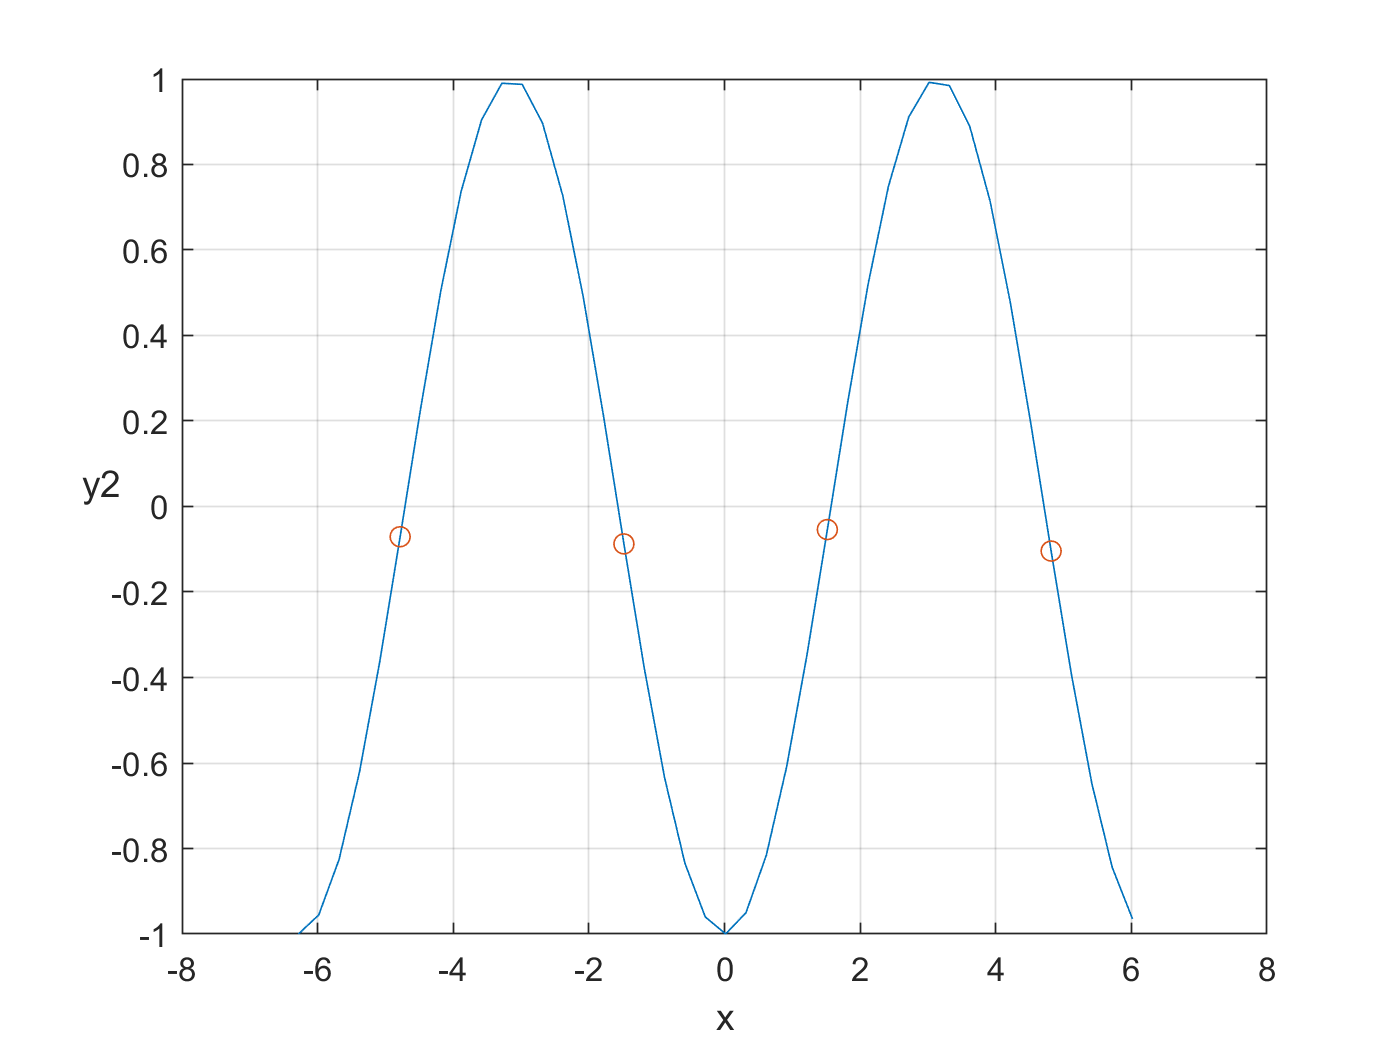

x_stationaryPoints_Q1 = x(offset);

figure(2);
plot(x, y2);xlabel('x');ylabel('y2','Rotation',0); %plot out seconde derivative
grid on;hold on; % from figure 2, we can know the inflection points are at x=-3pi/2, -pi/2, pi/2 and 3pi/2
offset2 = find(abs(y2)<0.15);
scatter(x(offset2),y2(offset2));

x_inflectionPoints_Q1 = x(offset2);

%x_stationaryPoints = [-2*pi -pi 0 pi 2*pi];
%f_stationaryPoints = cos(x_stationaryPoints);
%x_inflectionPoints = [-3*pi/2 -pi/2 pi/2 3*pi/2];
%f_inflectionPoints = cos(x_inflectionPoints);

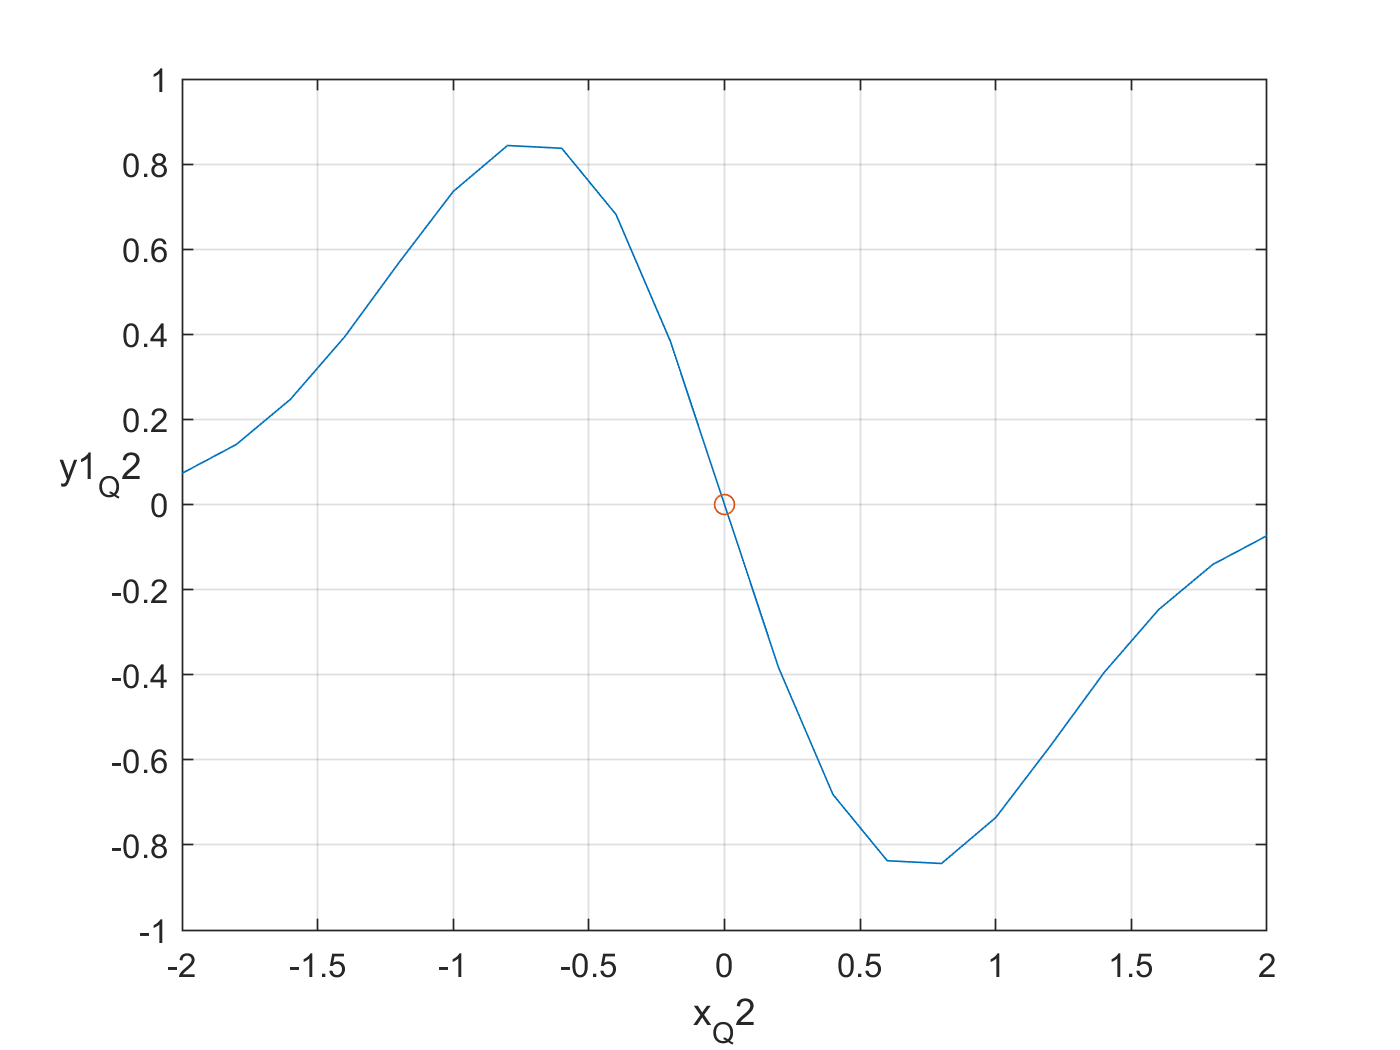

%%Qestion2
syms x %create symbolic variable
f_Q2 = exp(-x^2);
y1_Q2 = diff(f_Q2);%first derivative
y2_Q2 = diff(y1_Q2) == 0;%second derivative
x_inflectionPoints_Q2 = solve(y2_Q2, x);
x_Q2 = -2:0.2:2;
y1_Q2 = -2.*x_Q2.*exp(-x_Q2.^2);
y2_Q2 = 4.*x_Q2.^2.*exp(-x_Q2.^2) - 2.*exp(-x_Q2.^2);
figure(3);
plot(x_Q2, y1_Q2);xlabel('x_Q2');ylabel('y1_Q2','Rotation',0);%plot out first derivative
grid on;hold on;% from figure3, we can know the stationary points are only at x=0
offset3 = find(abs(y1_Q2)<0.05);
scatter(x_Q2(offset3),y1_Q2(offset3));

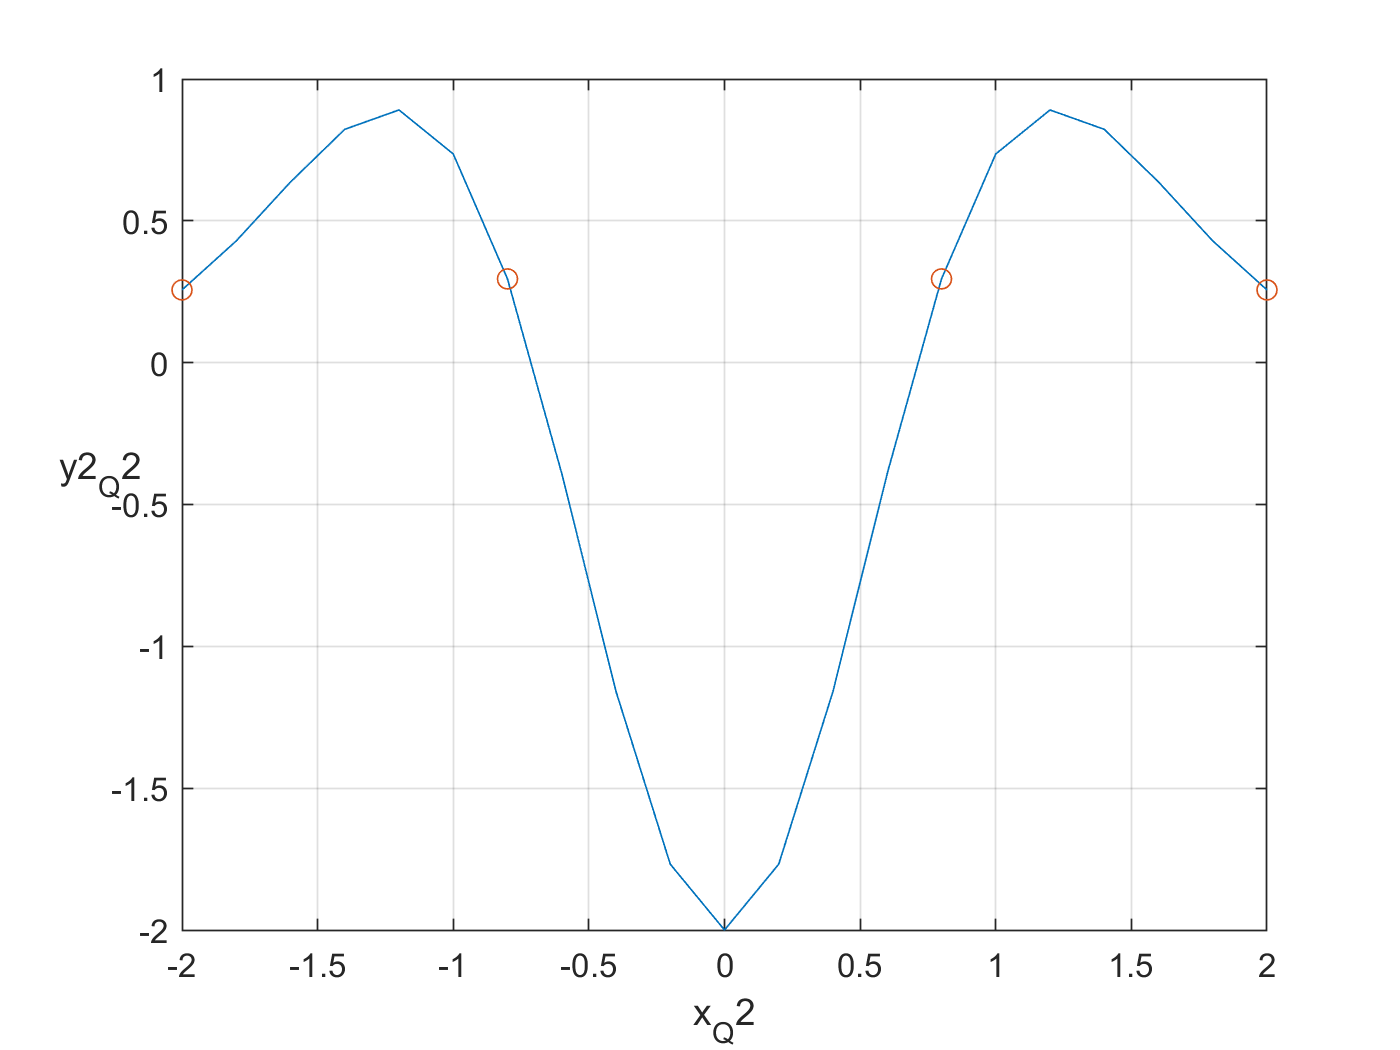

x_stationaryPoints_Q2 = x_Q2(offset3);

figure(4);
plot(x_Q2, y2_Q2);xlabel('x_Q2');ylabel('y2_Q2','Rotation',0);%plot out second derivative
grid on;hold on;% from figure3, we can know the inflection points are only at x=+-sqrt(2)/2
offset4 = find(abs(y2_Q2)<0.3);
scatter(x_Q2(offset4),y2_Q2(offset4));


%x_stationaryPoints_Q2 = 0;
%y_stationaryPoints_Q2 = exp(-x_stationaryPoints_Q2^2);
%y_inflectionPoints_Q2 = exp(-x_inflectionPoints_Q2.^2);

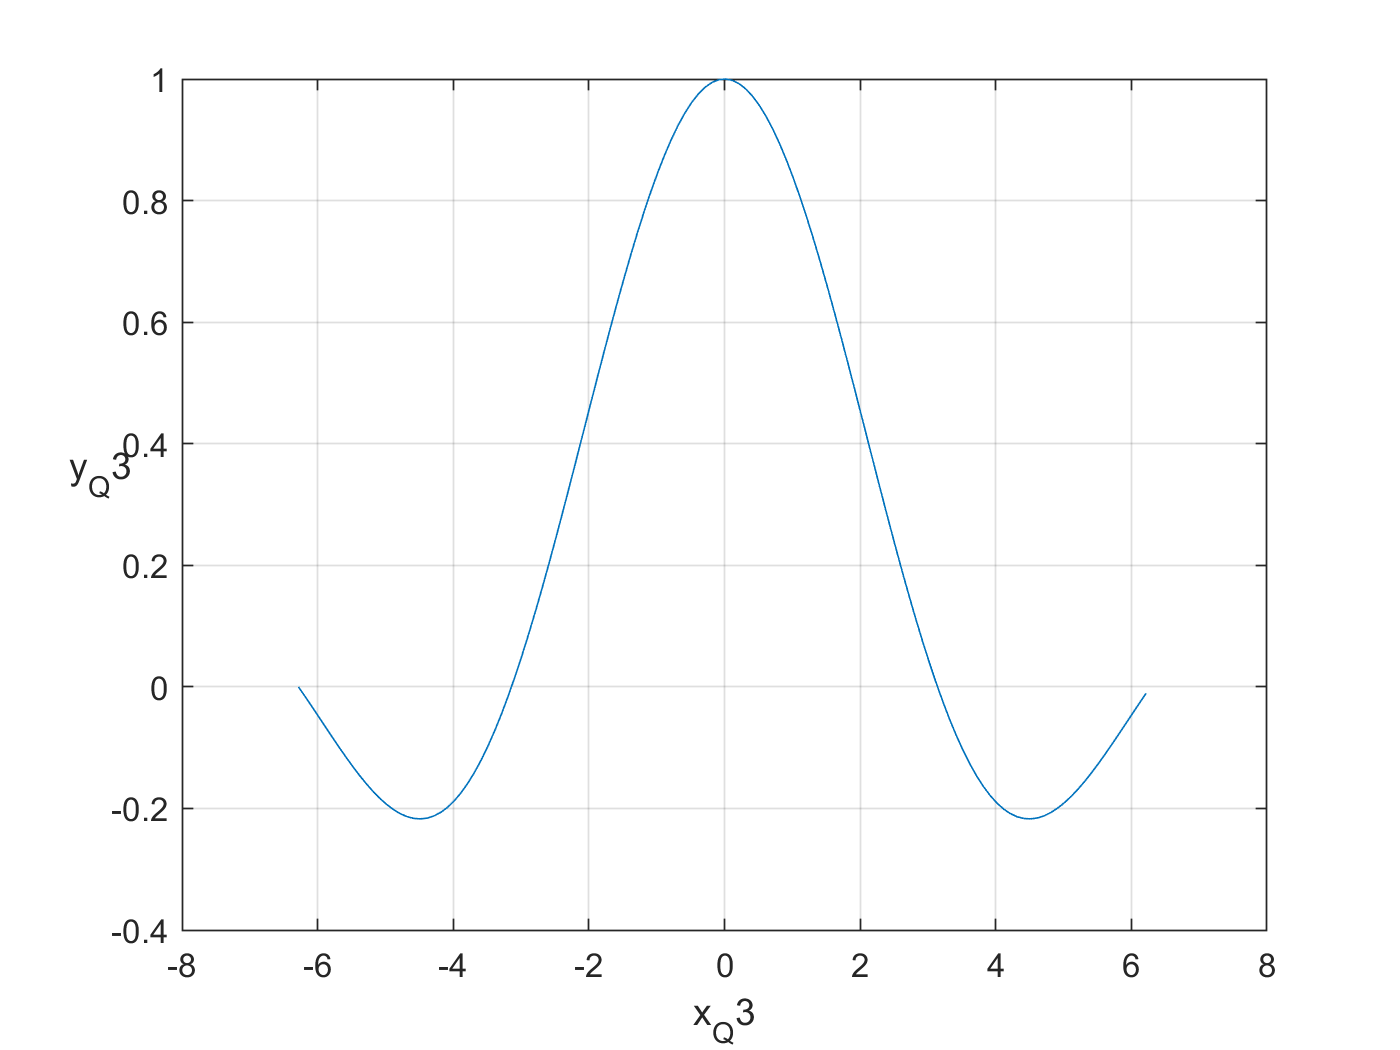

%%Question3
syms x
f_Q3 = sin(x)/x;
y1_Q3 = diff(f_Q3) == 0;
x_Q3 = -2*pi:0.1:2*pi;
y_Q3 = sin(x_Q3)./x_Q3;
figure(5);
plot(x_Q3, y_Q3);xlabel('x_Q3');ylabel('y_Q3','Rotation',0);%plot out function
grid on;% from figure5, we can know the global maximum is at x = 0, so there is no need to use first derivative

x_globalMax_Q3 = 0;
f_Q3 = sin(x_globalMax_Q3)/x_globalMax_Q3;% the max value is infinity.

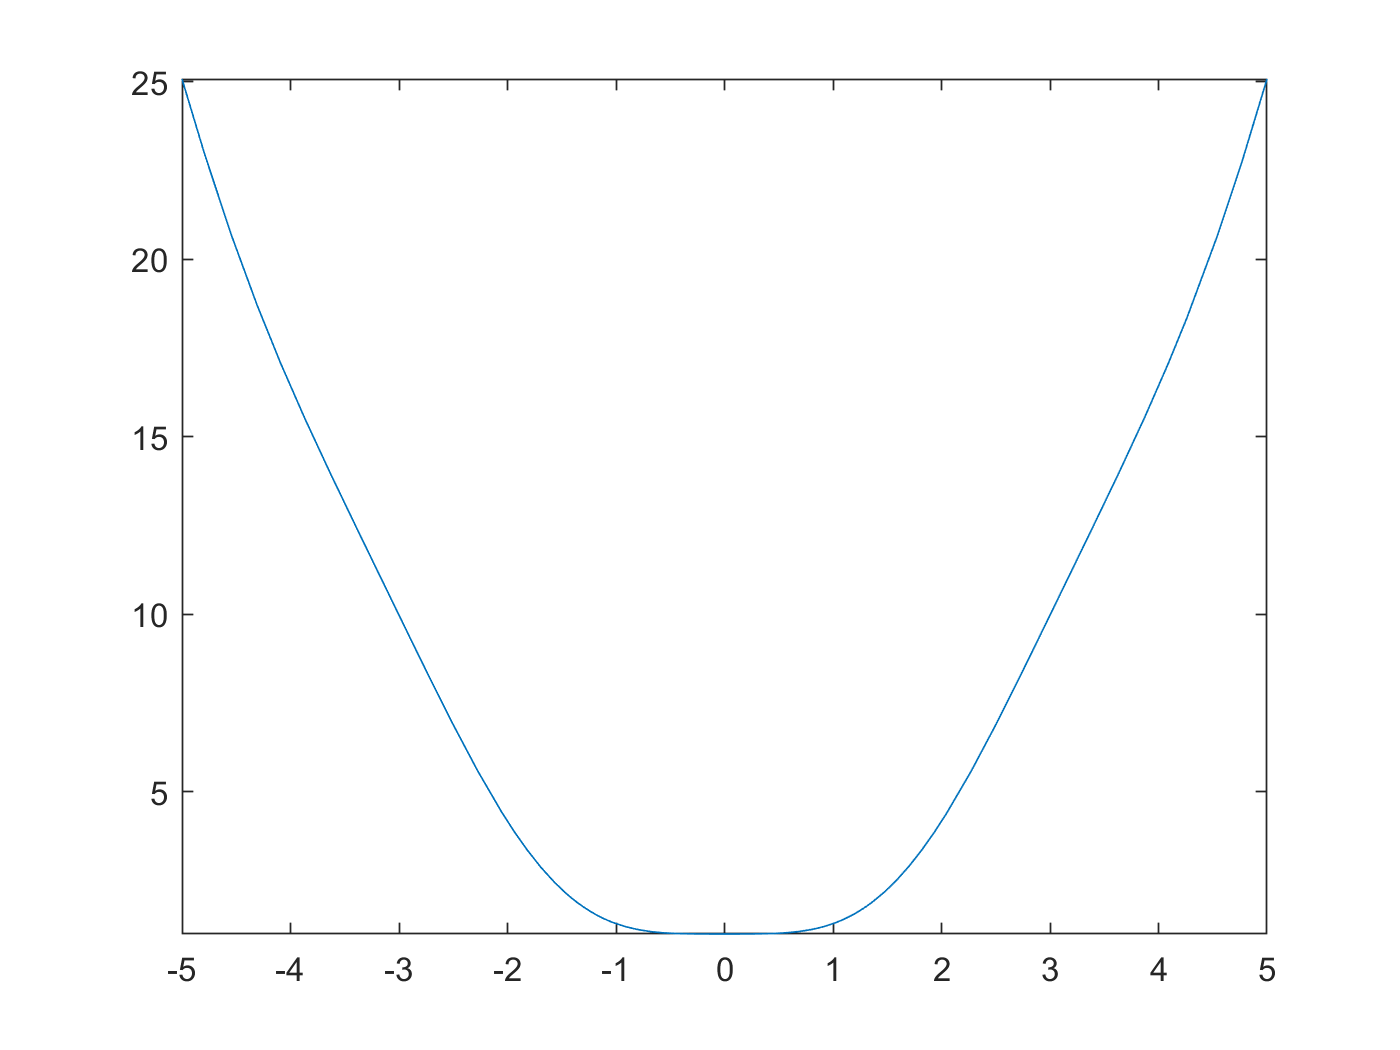

%%Question4
syms x
%x = -2*pi:0.1:2*pi;
k = [1 2 3 4 5];
f_k = x^2+k.*(cos(x)^2);
y_1 = f_k(1);
fplot(y_1);% the minimm point is at x = 0;

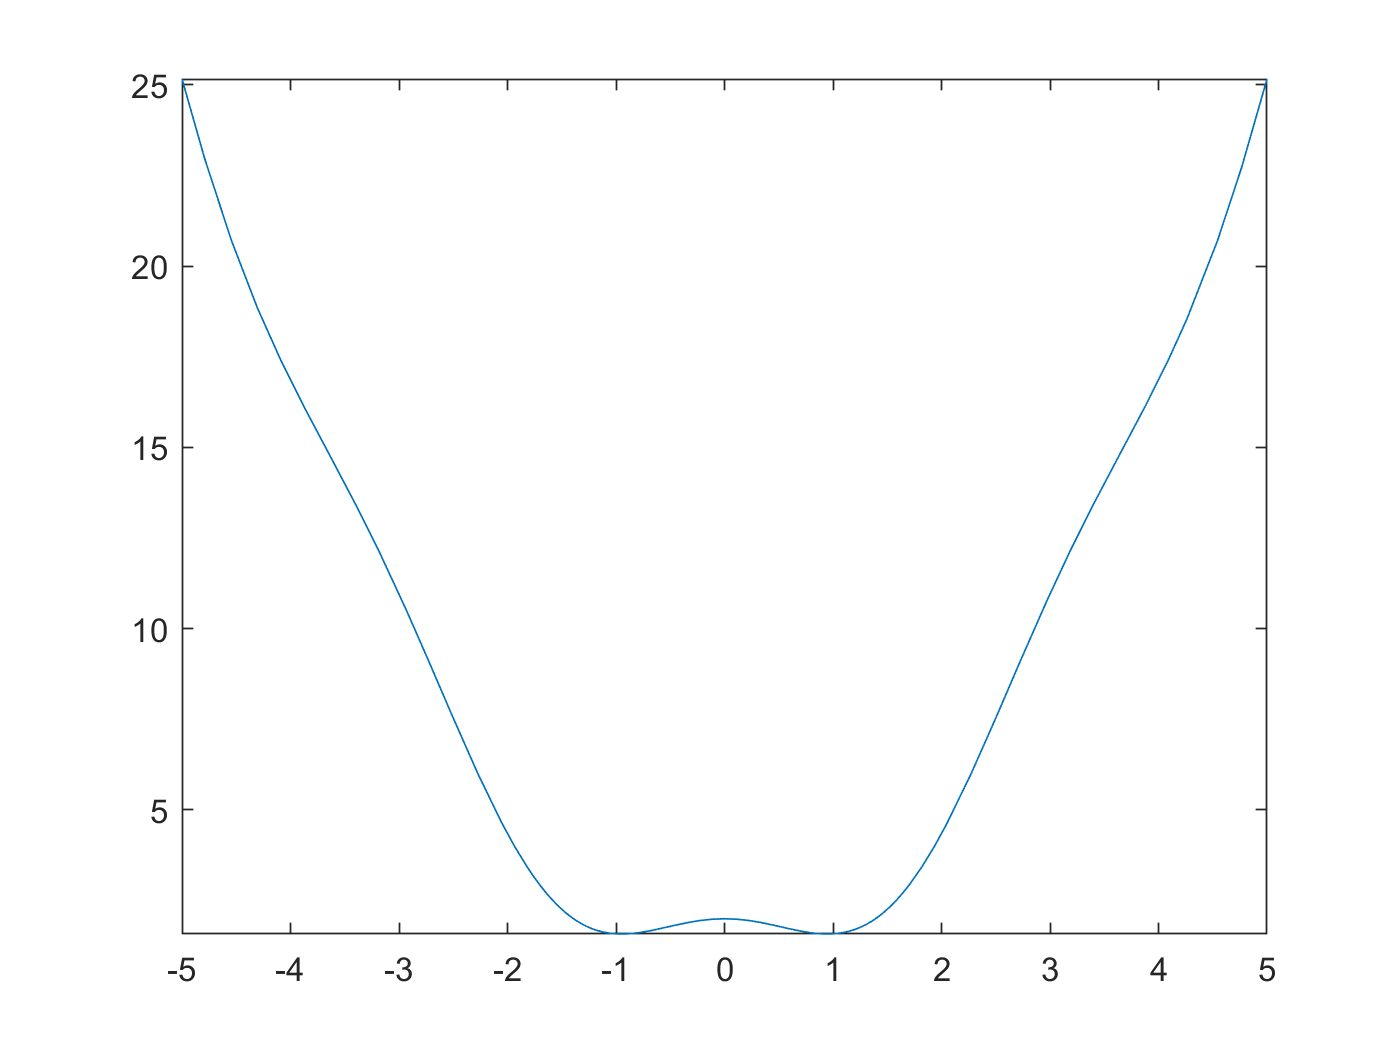

y_1_min = 0^2+1*cos(0)^2; % the min value is equal to 1

y_2 = f_k(2);
fplot(y_2);

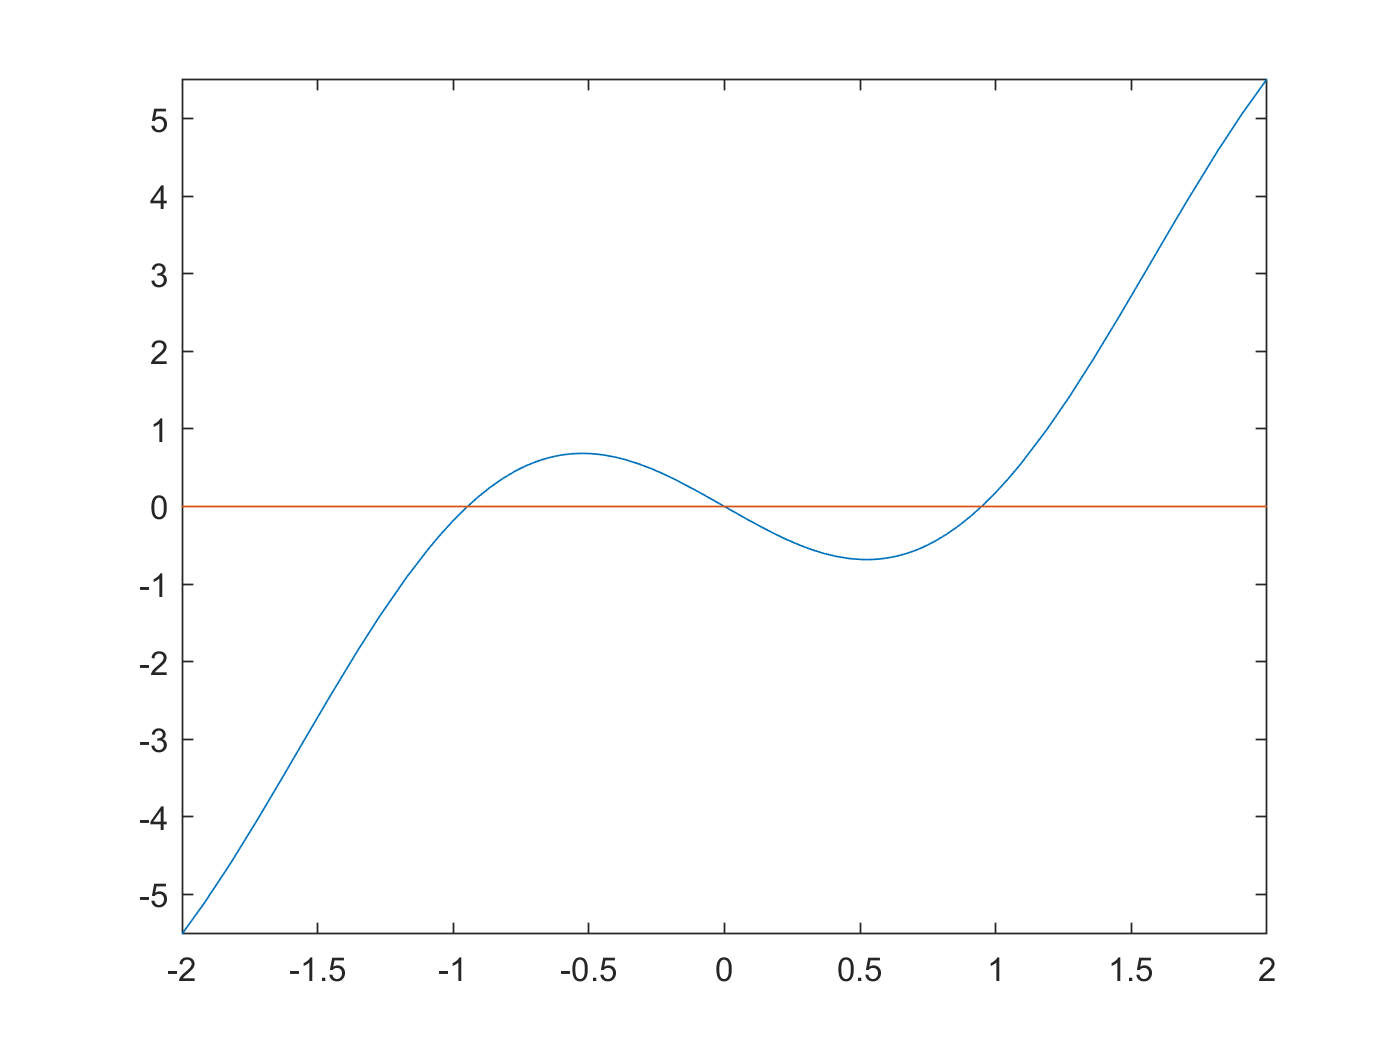

y_2firstD = diff(y_2) == 0;
fplot([lhs(y_2firstD) rhs(y_2firstD)], [-2 2]);% from the graph, the stationary points are at x=-0.9403&0.9144

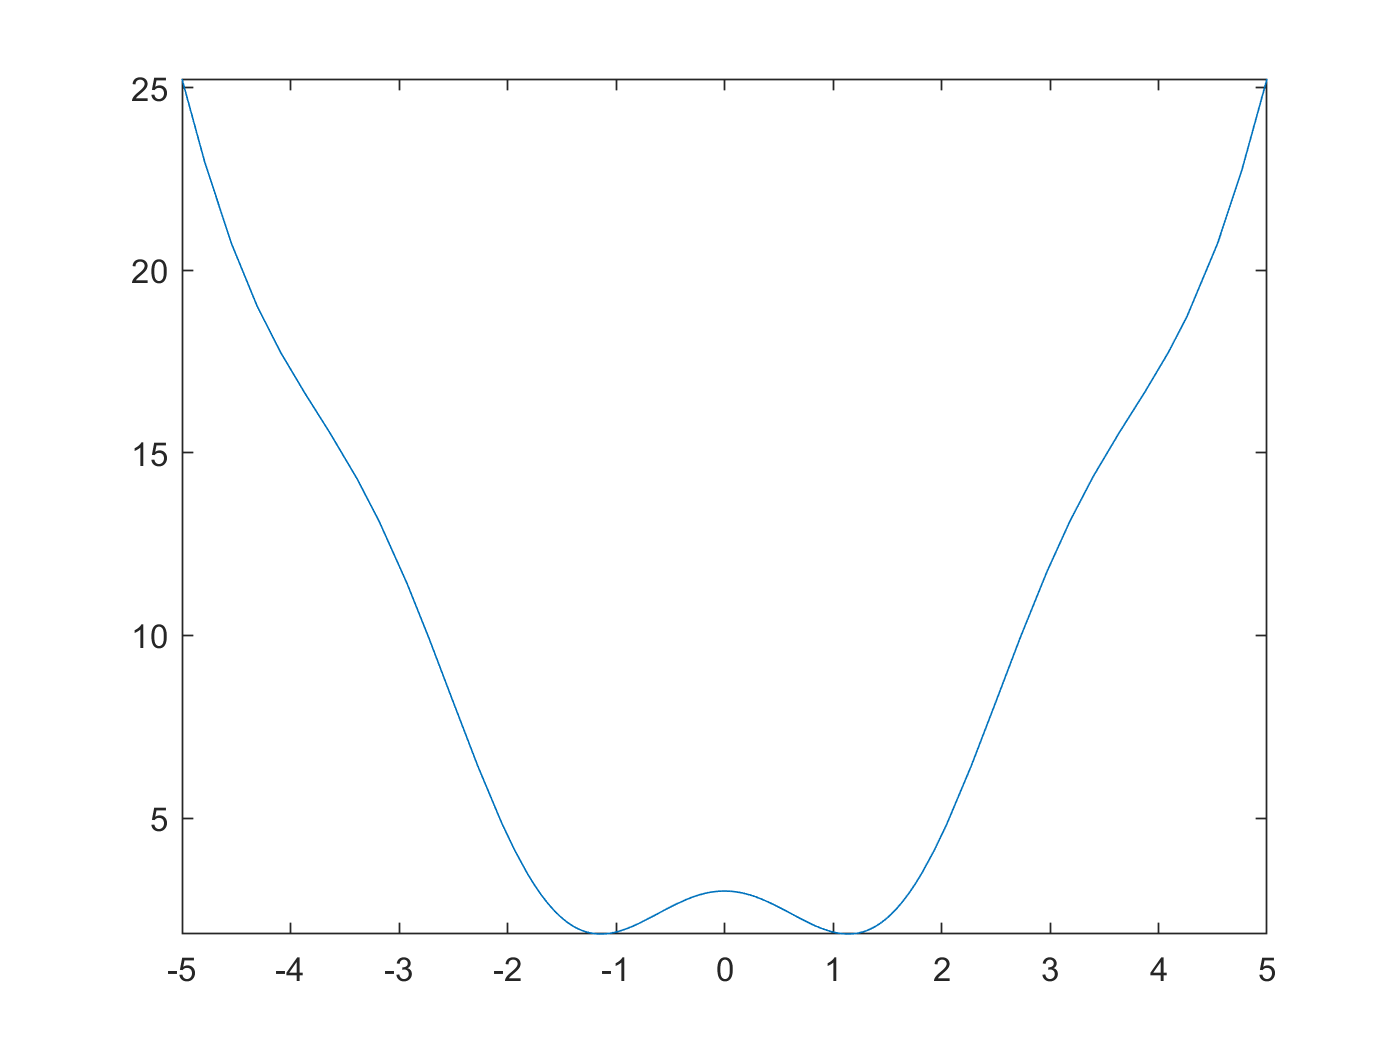

y_2min1 = (-0.9403)^2+1*cos(-0.9403)^2; %y_2min1 = 1.2317
y_2min2 = (0.9144)^2+1*cos(0.9144)^2; %y_2min2 = 1.2086

y_3 = f_k(3);
fplot(y_3);

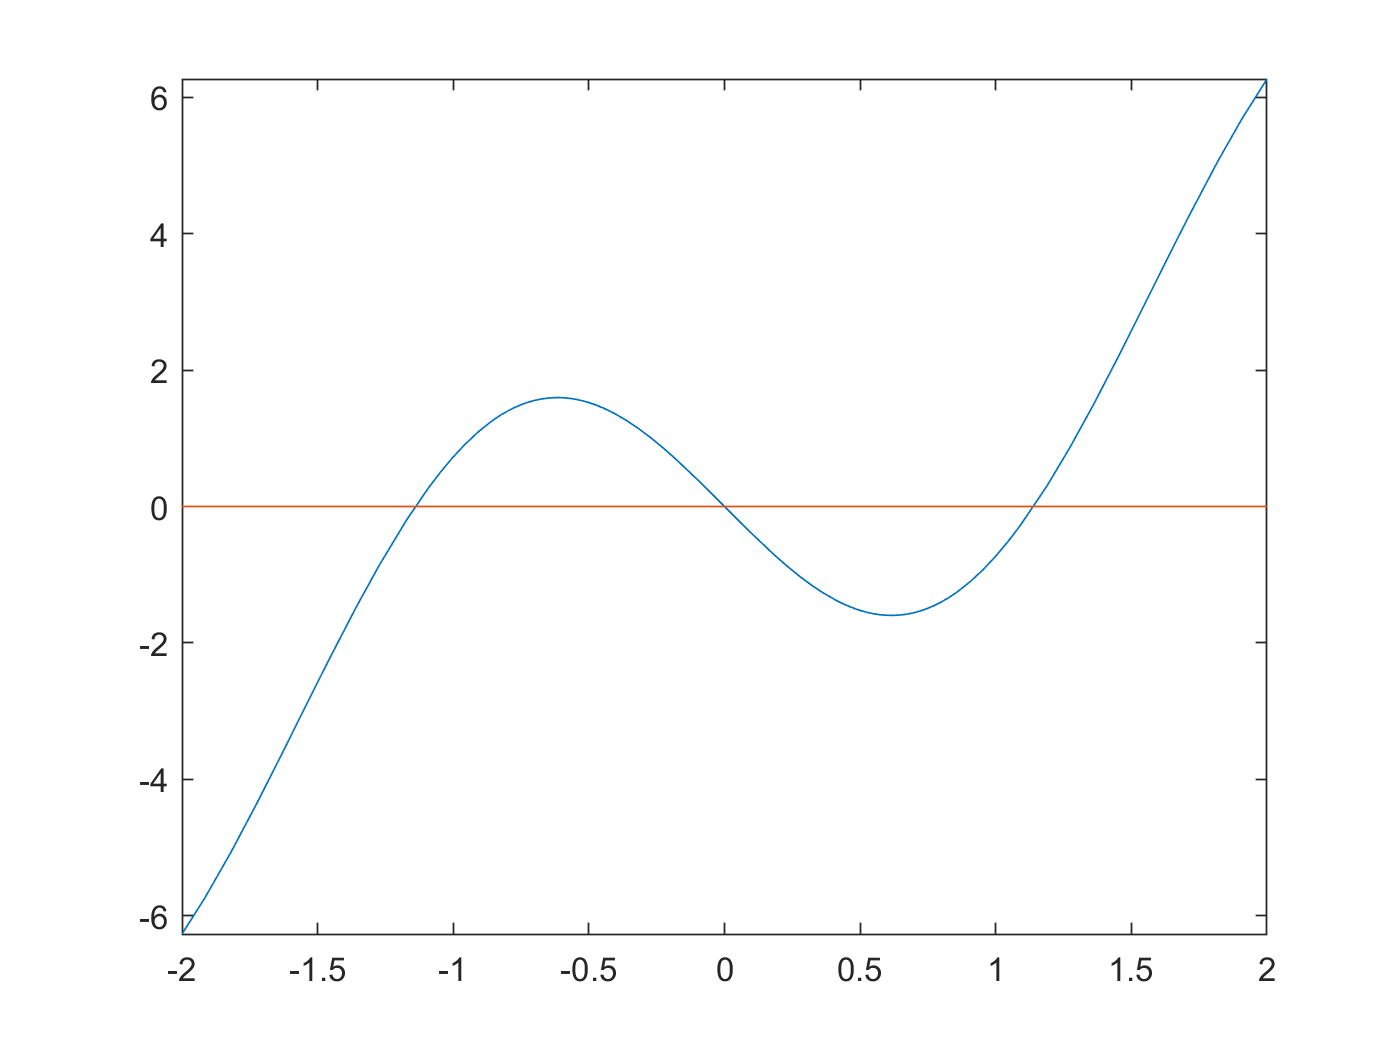

y_3firstD = diff(y_3) == 0;
fplot([lhs(y_3firstD) rhs(y_3firstD)], [-2 2]);

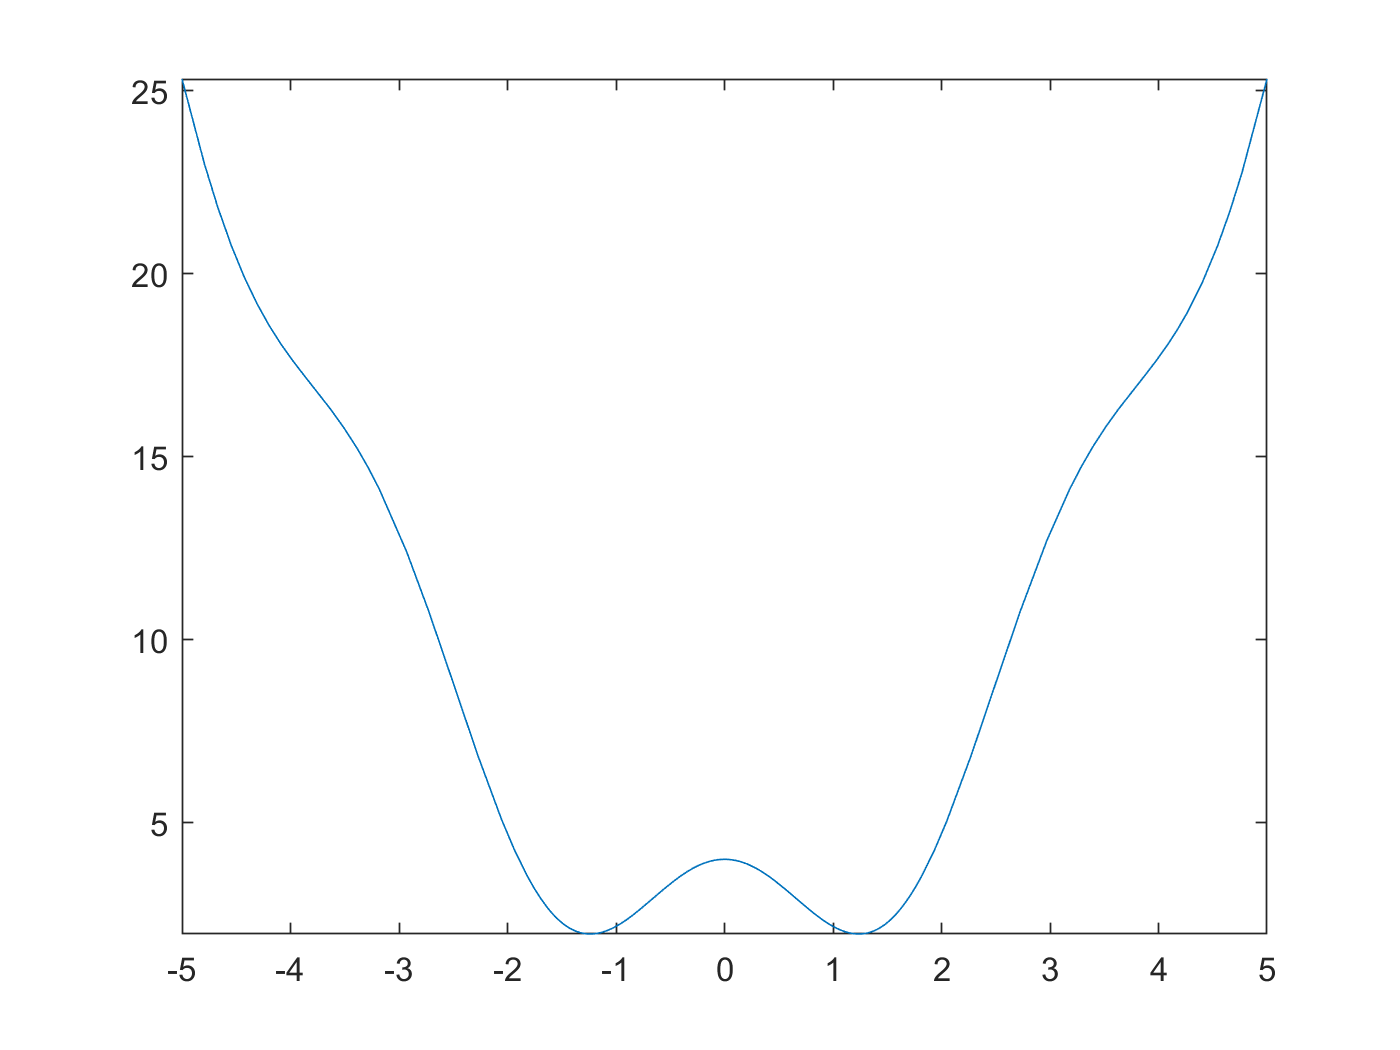

x_stationartPoints_y3 = vpasolve(y_3firstD, x, [1 2]);%from the graph, the stationary points are at x=1.139
y_3min = (1.139)^2+1*cos(1.139)^2; %y_3min = 1.4725

y_4 = f_k(4);
fplot(y_4);

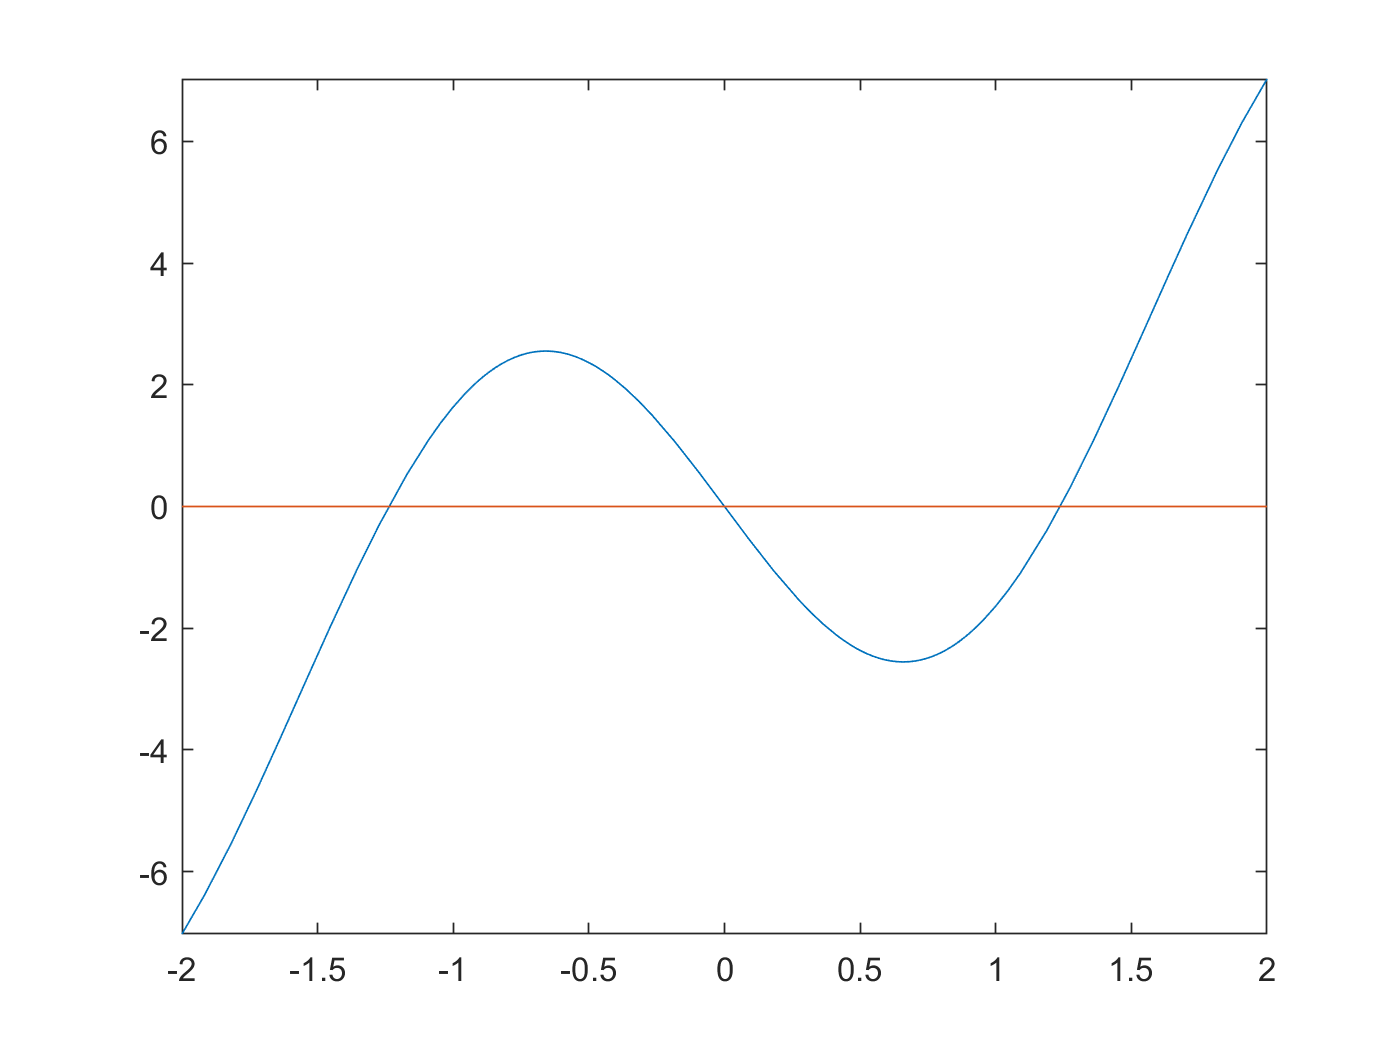

y_4firstD = diff(y_4) == 0;
fplot([lhs(y_4firstD) rhs(y_4firstD)], [-2 2]);%from the graph, the stationary points are at x=1.241

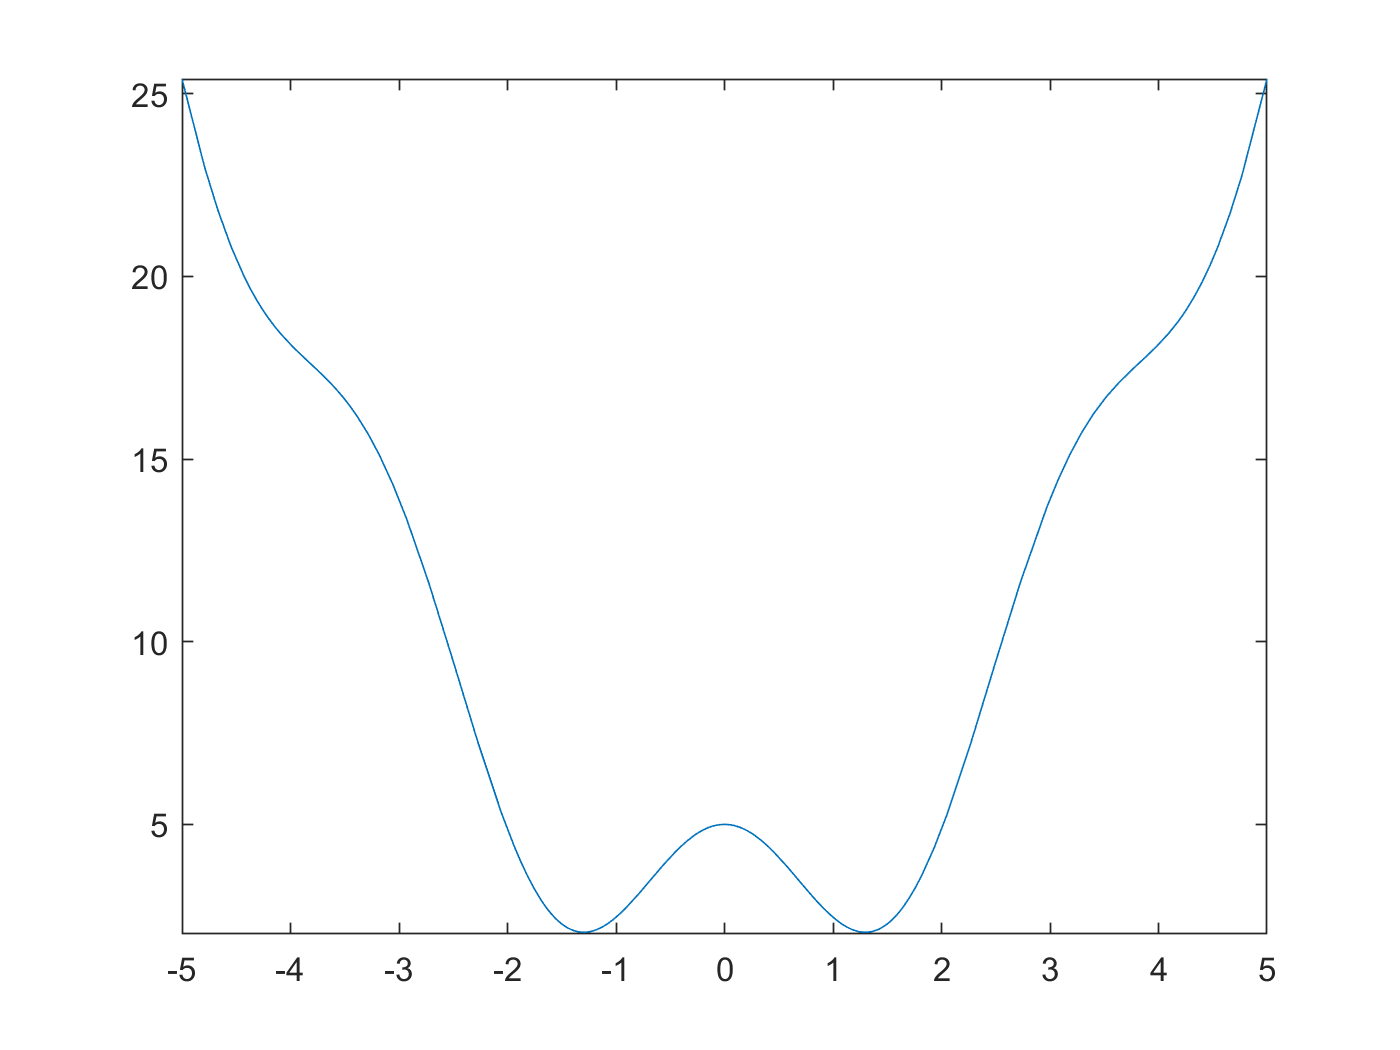

y_4min = (1.241)^2+1*cos(1.241)^2; %y_4min = 1.645

y_5 = f_k(5);
fplot(y_5);

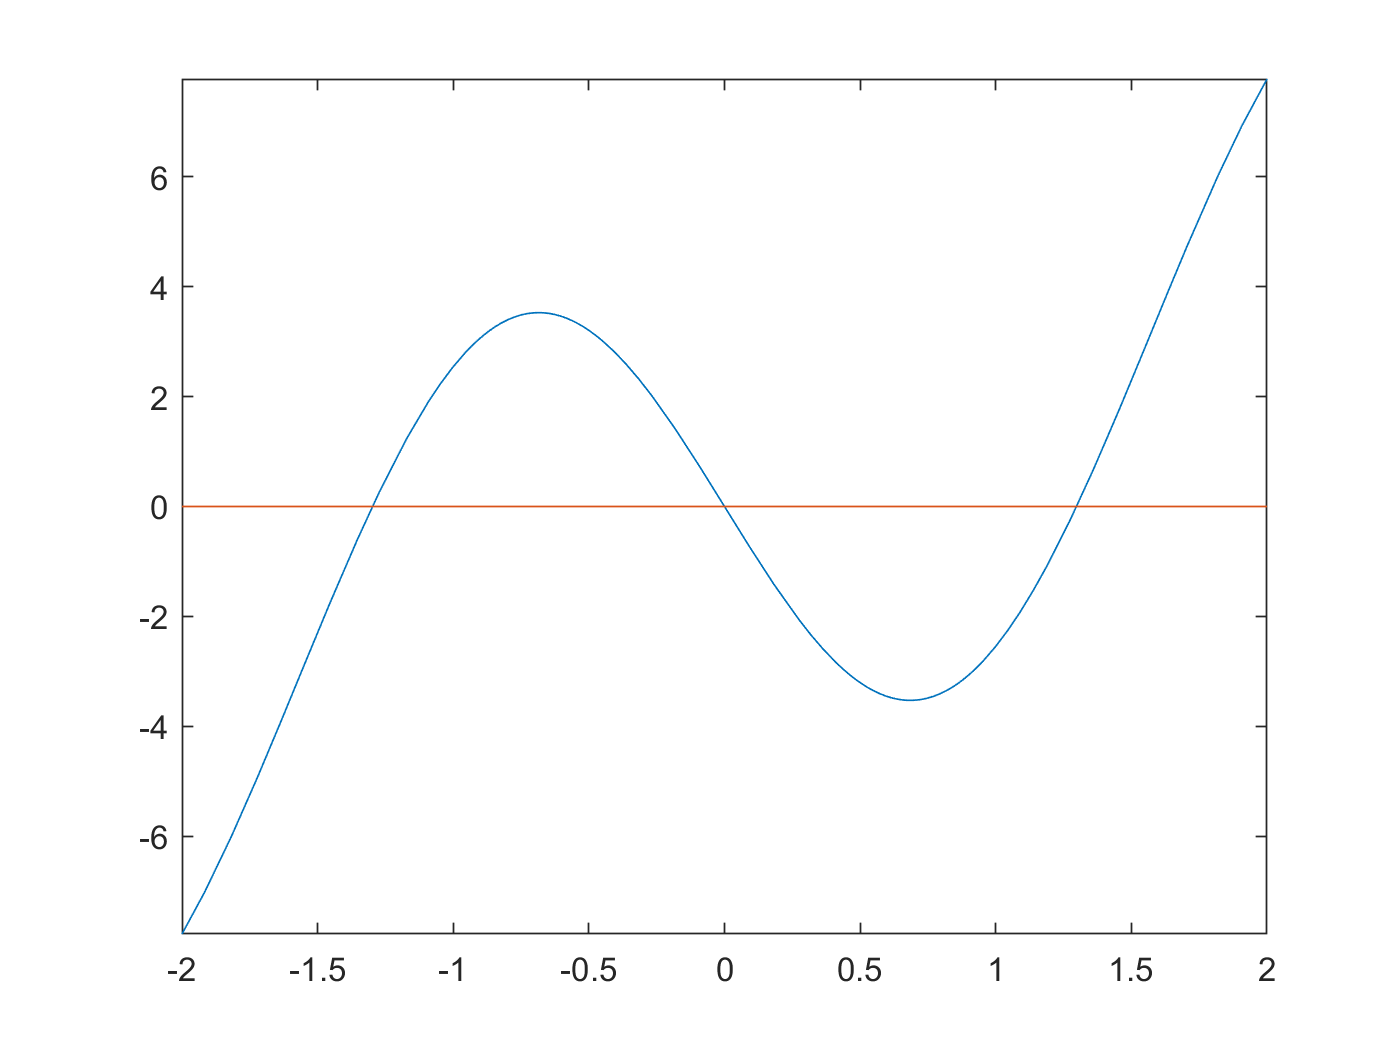

y_5firstD = diff(y_5) == 0;
fplot([lhs(y_5firstD) rhs(y_5firstD)], [-2 2]);%from the graph, the stationary points are at x=1.3

y_5min = (1.3)^2+1*cos(1.3)^2; %y_5min = 1.7616

% comments: As the value of k increasing, the graph of original function
% will be horizontally expanded along the x-axis, and the minimun points is
% going to move up.

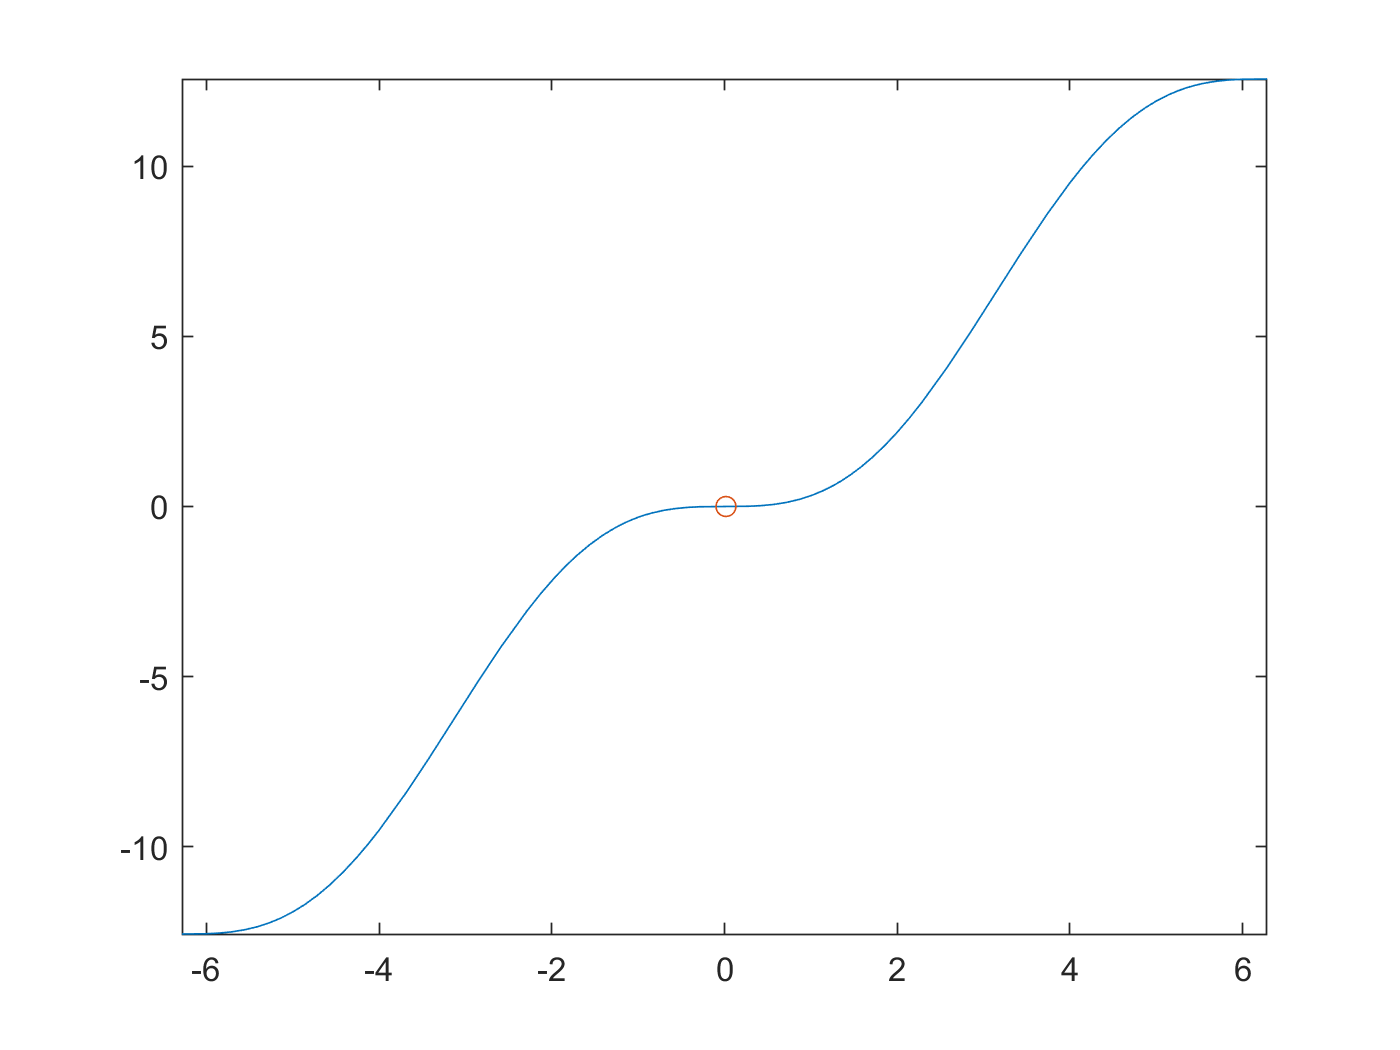

%%Question5
syms x y
%x = -2*pi:0.3:2*pi;
%y = -2*pi:0.3:2*pi;
%[x,y] = meshgrid(-2*pi:0.3:2*pi,-2*pi:0.3:2*pi);
f_Q5 = 2*cos(x)+x^2+y^2;
%surf(x, y, f_Q5);
D1_x = diff(f_Q5, x);
figure(6);
fplot(D1_x, [-2*pi 2*pi]);
hold on;
x = -2*pi:0.3:2*pi;
D1_x = 2.*x - 2*sin(x);
offset_1 = find(abs(D1_x) < 0.006);
scatter(x(offset_1), D1_x(offset_1));

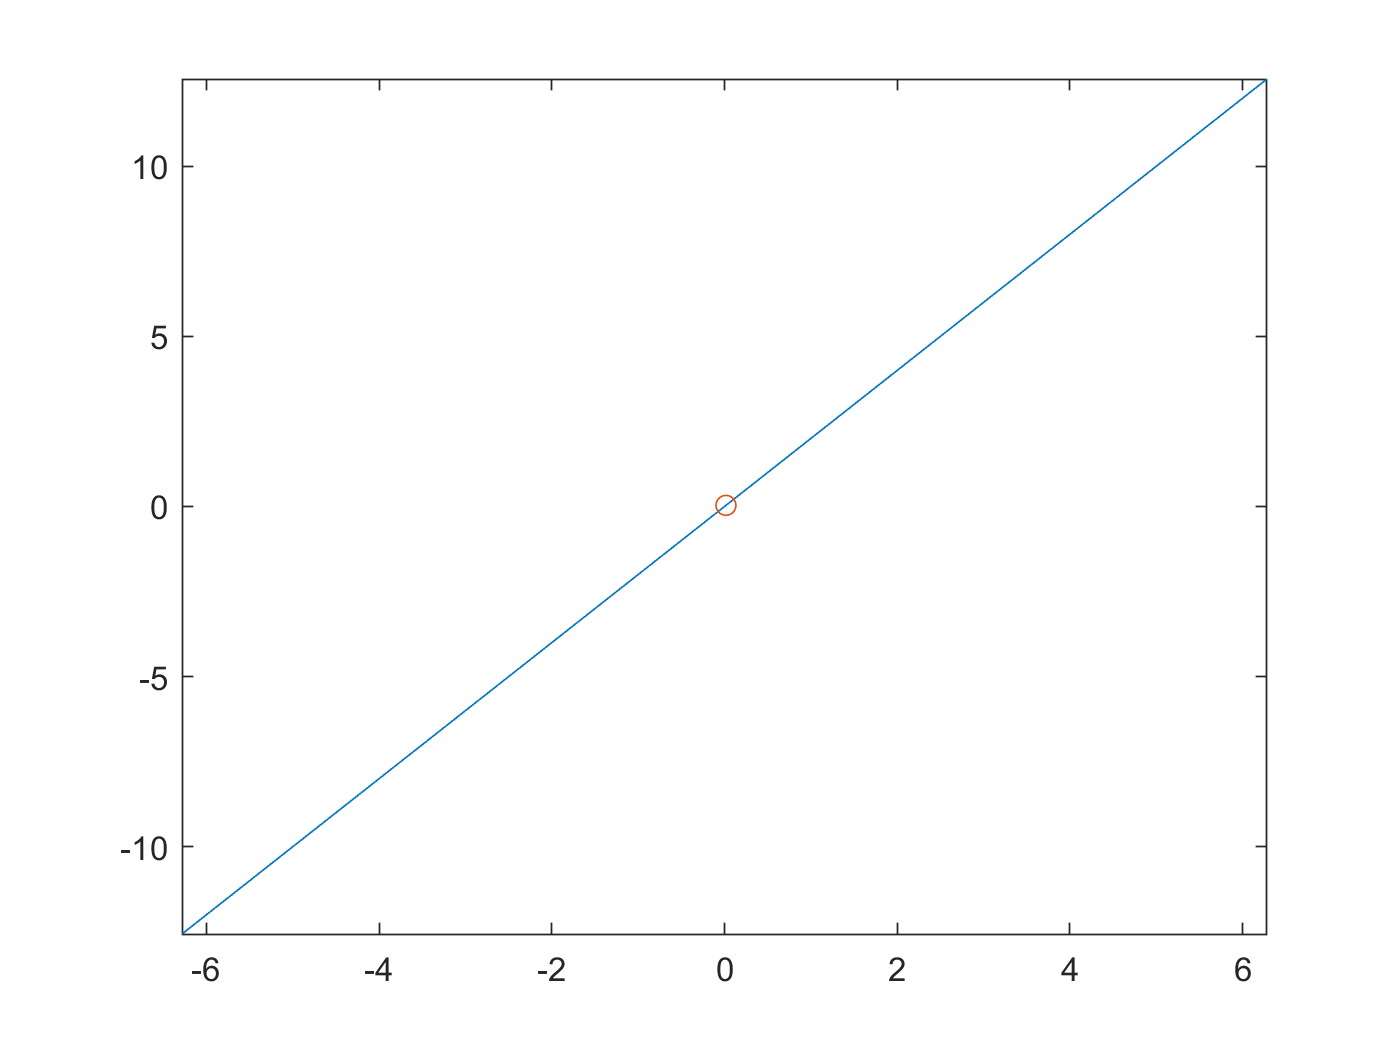

x_stationaryPoints_Q5 = x(offset_1);

D1_y = diff(f_Q5, y);
figure(7);
fplot(D1_y, [-2*pi 2*pi]);
hold on;
y = -2*pi:0.3:2*pi;
D1_y = 2*y;
offset_2 = find(abs(D1_y) < 0.05);
scatter(x(offset_2), D1_y(offset_2));

y_stationaryPoints_Q5 = y(offset_2);

min_Q5 = 2*cos(x_stationaryPoints_Q5)+x_stationaryPoints_Q5^2+y_stationaryPoints_Q5^2;

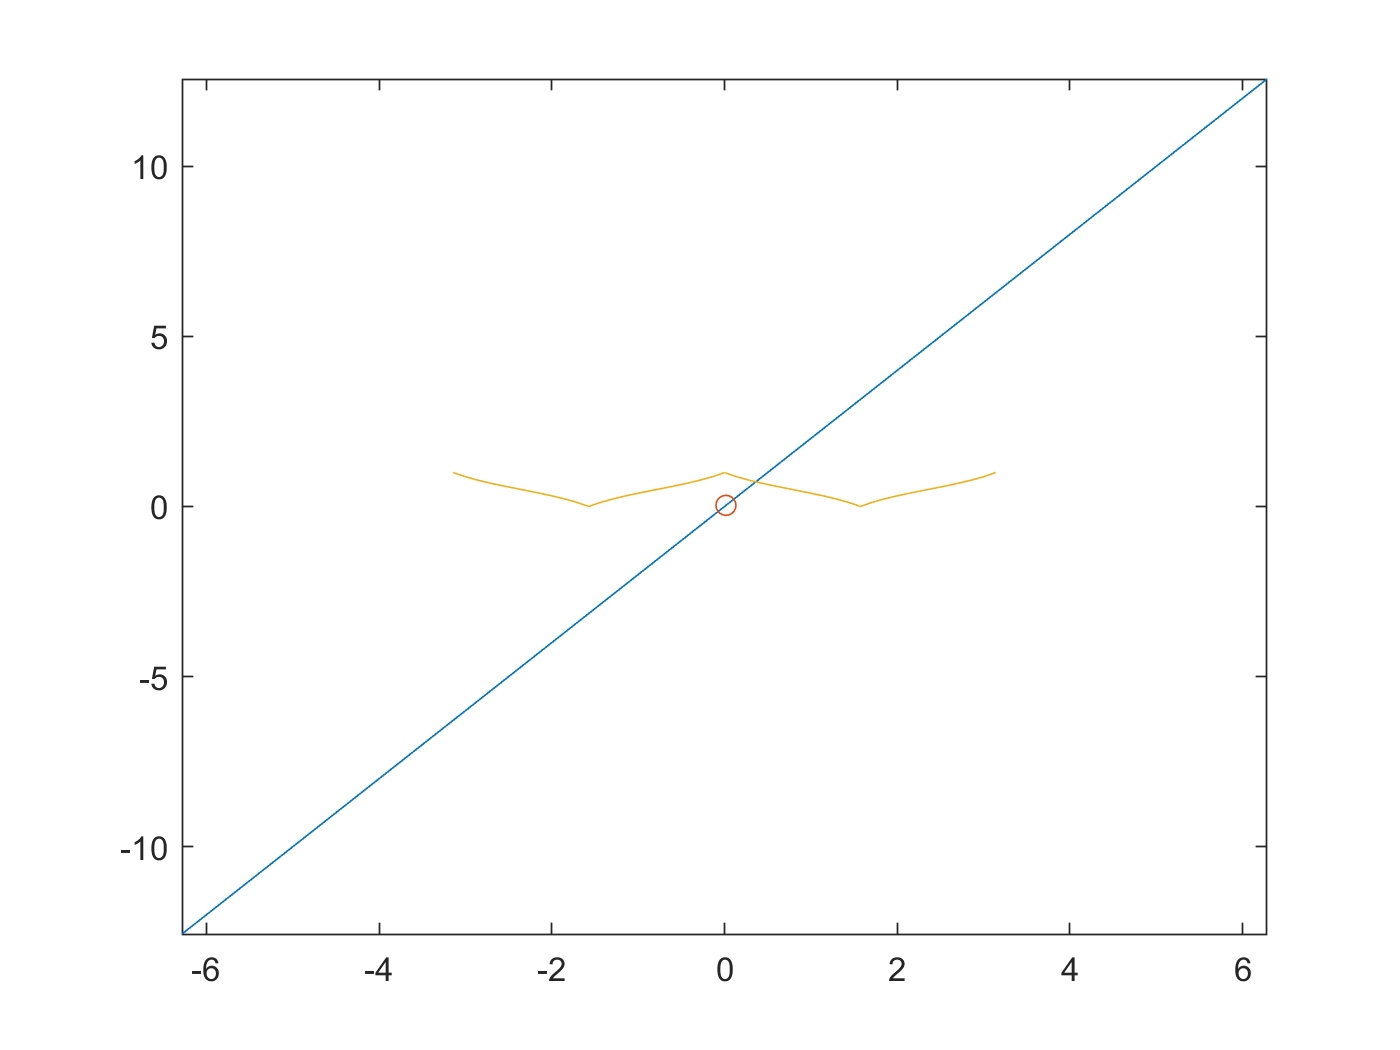

%%Question6
syms x
f_Q5 = 1/(1+abs(tan(x)));
fplot(f_Q5, [-pi pi]); % referring to the plotting, obviously, the local max of 1 is located at x = -pi, 0, pi

x = -pi:0.01:pi;
f_Q5 = 1./(1+abs(tan(x)));
TF = islocalmin(f_Q5);
x_minPoints = x(TF); % the local min of 0 are located at x = +-1.57
%the difficulties of this problem are how to find the locations of minimun
%value.

%%Question7
A = [2 3; 3 5];
D1_A = 2;
D2_A = det(A);% this is equal to 1
% the both of leading minor are positive, so this matrix is positve
% definite

B = [-2 2; 2 3];
D1_B = -2;
D2_B = det(B);% this is equal to -10
%cause the two leading minors are both negative, the matrix is negative
%definite

C = [-5 2; 2 -2];
D1_C = -5;
D2_C = det(B);% this is equal to 6
%cause the two leading minors are negative and positive, the matrix is
%indefinite

%%Question 8
syms x y
f_1 = x^2+exp(y);
H_1 = hessian(f_1, [x y]);
% the two minors are both positive,2 and 2*exp(y), so the matrix is
% positvive definite

syms x y
f_2 = 1-x^2-y^2;
H_2 = hessian(f_2, [x y]);
%cause the two leading minors are negative and positive, -2 and 4, the matrix is
%indefinite

syms x y
f_3 = x*y;
H_3 = hessian(f_3, [x y]);
%cause the two leading minors are negative and zero, -1 and 0, the matrix is
%indefinite